# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 14-Mar-2020 08:17:03

## Create the Array of Layers

layers = [
    imageInputLayer([1024 1 1],"Name","input")
    convolution2dLayer([3 1],64,"Name","conv1_1","Padding",[1 1 0 0])
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 1],64,"Name","conv1_2","Padding",[1 1 0 0])
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 1],"Name","pool1")
    convolution2dLayer([3 1],128,"Name","conv2_1","Padding",[1 1 0 0])
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 1],128,"Name","conv2_2","Padding",[1 1 0 0])
    reluLayer("Name","relu2_2")
    maxPooling2dLayer([2 1],"Name","pool2")
    convolution2dLayer([3 1],256,"Name","conv3_1","Padding",[1 1 0 0])
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 1],256,"Name","conv3_2","Padding",[1 1 0 0])
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 1],256,"Name","conv3_3","Padding",[1 1 0 0])
    reluLayer("Name","relu3_3")
    convolution2dLayer([3 1],256,"Name","conv3_4","Padding",[1 1 0 0])
    reluLayer("Name","relu3_4")
    maxPooling2dLayer([2 1],"Name","pool3")
    convolution2dLayer([3 1],512,"Name","conv4_1","Padding",[1 1 0 0])
    reluLayer("Name","relu4_1")
    convolution2dLayer([3 1],512,"Name","conv4_2","Padding",[1 1 0 0])
    reluLayer("Name","relu4_2")
    convolution2dLayer([3 1],512,"Name","conv4_3","Padding",[1 1 0 0])
    reluLayer("Name","relu4_3")
    convolution2dLayer([3 1],512,"Name","conv4_4","Padding",[1 1 0 0])
    reluLayer("Name","relu4_4")
    maxPooling2dLayer([2 1],"Name","pool4")
    convolution2dLayer([3 1],512,"Name","conv5_1","Padding",[1 1 0 0])
    reluLayer("Name","relu5_1")
    convolution2dLayer([3 1],512,"Name","conv5_2","Padding",[1 1 0 0])
    reluLayer("Name","relu5_2")
    convolution2dLayer([3 1],512,"Name","conv5_3","Padding",[1 1 0 0])
    reluLayer("Name","relu5_3")
    convolution2dLayer([3 1],512,"Name","conv5_4","Padding",[1 1 0 0])
    reluLayer("Name","relu5_4")
    maxPooling2dLayer([2 1],"Name","pool5")
    fullyConnectedLayer(16,"Name","fc6")
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(16,"Name","fc7")
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop7")
    fullyConnectedLayer(4,"Name","fc8")
    softmaxLayer("Name","prob")
    classificationLayer("Name","output")];

## Plot the Layers

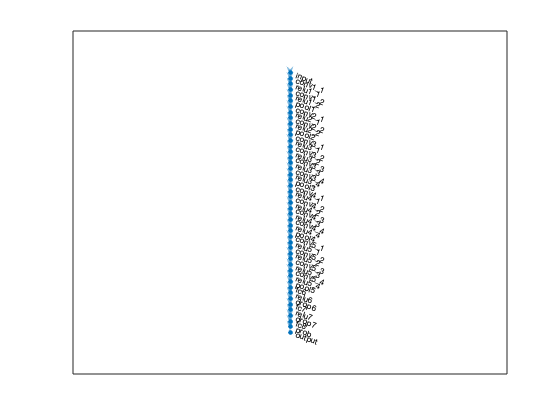

plot(layerGraph(layers));